# **Agentic Engineering: When AI Stops Suggesting and Starts Doing**

This live script walks through a data analysis pipeline using agentic AI and low-code tools. The intent is to illustrate how combining agentic AI with trusted engineering tools can accelerate development efficiently without compromising verification and rigor. 

## 1. Background

This demo showcases a pipeline design workflow using MATLAB and Simscape Fluids to size a water transportation system and select an appropriate pump. Starting from pipeline geometry, elevation changes, flow requirements, outlet pressure, and operating constraints, the model generates system curves that account for frictional and hydro static effects.

The modeling is done with Simulink and Simscape. You can learn more about physical modeling with Simulink and Simscape [here](https://www.mathworks.com/help/overview/physical-modeling.html).

This live script follows a typical data analysis and modeling workflow:

- **Access Data** from our Simulink model (Agentic)

- **Preprocess Data** and extract useful features for training (Agentic)

- **Develop Predictive Model** to diagnose pipe leak condition (Classification Learner app)

- **Integrate Analytics and Deploy** to a monitoring app (Agentic)

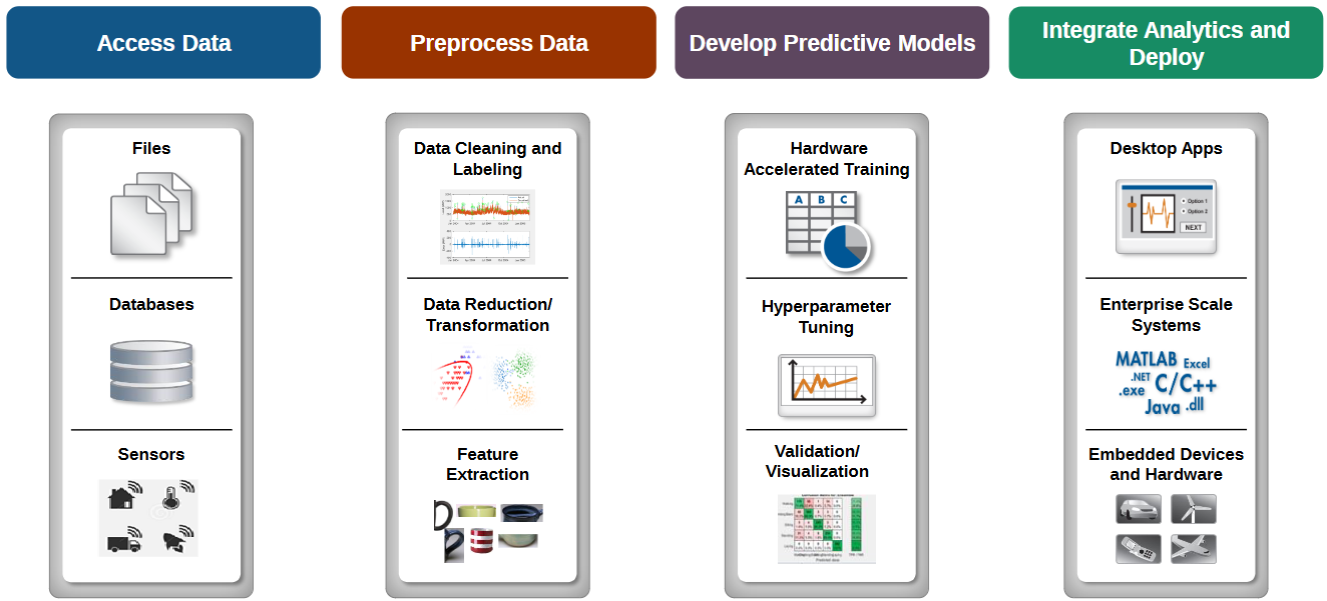

## 2. Requirements

To run this demo, you will need:

- Access to an agent that complies with the Model Context Protocol, e.g. Claude Code, GitHub® Copilot, OpenAI® Codex, Gemini™ CLI, Amp

- Enough tokens

- Local installation of MATLAB R2026a. For Rice students, you can download MATLAB [here](https://www.mathworks.com/academia/tah-portal/rice-university-40580441.html).

- MATLAB MCP Server with the MATLAB Agentic Toolkit & Simulink Agentic Toolkits. To install and set up, follow the instructions [here](https://github.com/matlab/matlab-mcp-server).

## 3. Planning

A data analysis workflow starts with a need. In this case, we want to create a monitoring app that will enable a field engineer to diagnose leak conditions in the pipeline using available sensor data. We will develop and test our monitoring app virtually, using the Simulink model. Starting in the computer before moving to the real world (AKA Model-Based Design) is an approach that saves time and resources and it's widely used in the industry.  

### 3.1 Explain Model

We may not be familiar with the Simulink model. Luckily, the agent can inspect and run the model and give us an overview of how it works.

**Human Expertise matters: **We are still responsible for corroborating the output and making sure that it conforms with our expectations.

Prompt 1:

 
Prompt1 = "review the files in this directory, familiarize yourself with this demo, use the Pipeline Design Demo.docx in the Design folder for reference";
clipboard("copy",Prompt1)

My results:

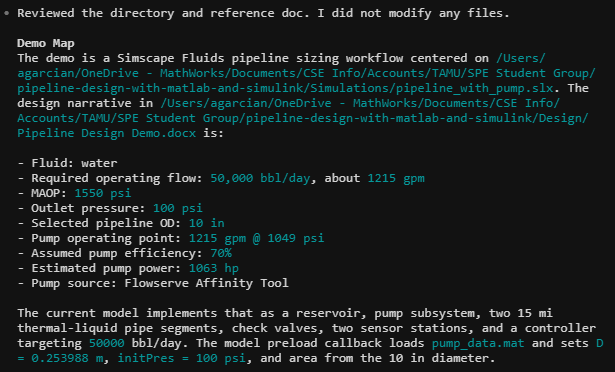

**Pro Tip: Record context (plans, analyses, instructions) **

Agents don't have memory - when the session ends, they forget everything. Also, complex tasks and long conversations may exhaust context capacity and degrade performance. Recording your plan and ancillary context can help you and the agent stay on track.

Prompt 2:

 
Prompt2 = "Capture what you learned in a markdown file in the Markdowns folder";
clipboard("copy",Prompt2)

My results:

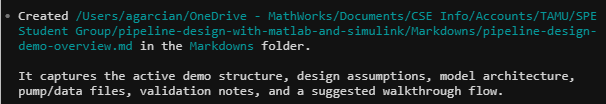

 
open('pipeline-design-demo-overview.md');

### 3.2 Visualize signals

This model generates quite a bit of information. We can probe signals, output them and plot them for analysis. Here we ask the model to create a script that runs the model and extracts flow rate data.

**Human Expertise matters: **It helps to know which data matters and how to "interrogate it" using the right analysis and visualization techniques.

**Pro Tip: Ask the agent to generate scripts or functions. You can reuse this code for future analysis and save time... and tokens!**

Prompt 3:

 
Prompt3 = "Create code that runs pipeline_with_pump.slx for 10 seconds and creates a plot of pump flowrate in gallons per minute (GPM). Save it to the Scripts folder";
clipboard("copy",Prompt3)

My results:

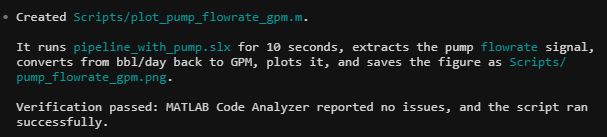

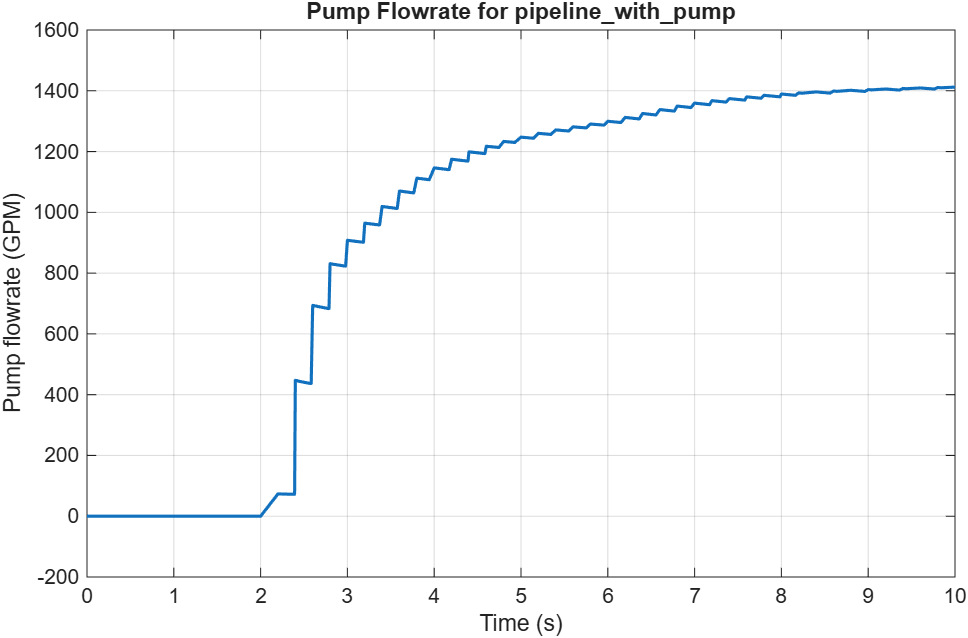

 
open('plot_pump_flowrate_gpm');

### 3.3 How to simulate leak condition

Prompt 4:

 
Prompt4 = "how can I simulate independent leaks in the pipeline segments of the simscape model pipeline_with_pump?";
clipboard("copy",Prompt4)

My results:

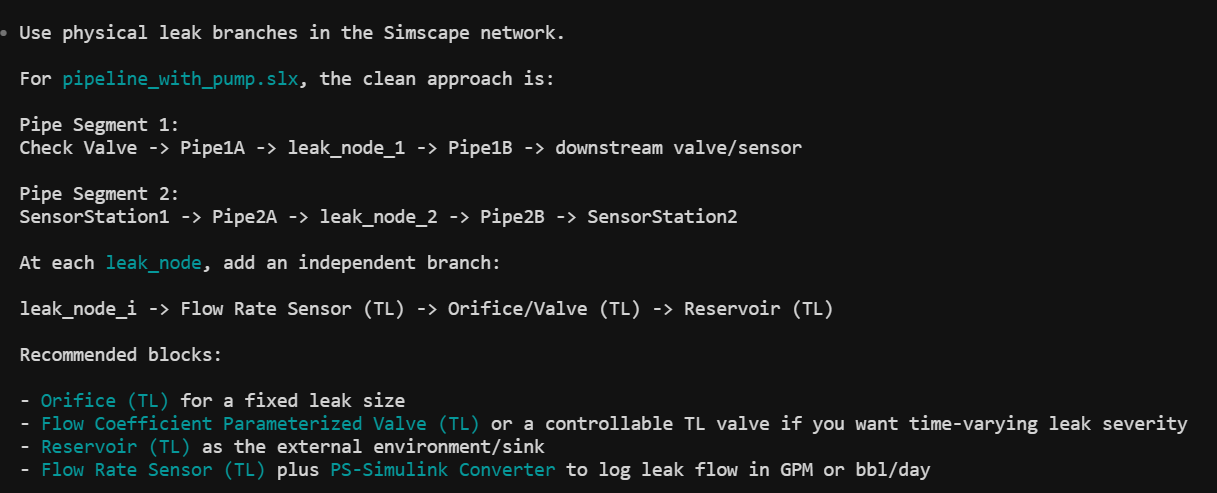

In this case we ask the agent to implement a flow coefficient parameterized valve to adjust the size of the leak.

Prompt 5:

 
Prompt5 = "implement the parameterized valve to independently control leaks in either segment. Implement the changes in model pipeline_with_pump_leaks.slx";
clipboard("copy",Prompt5)

My results (after re-organizing the blocks and signals for readability):

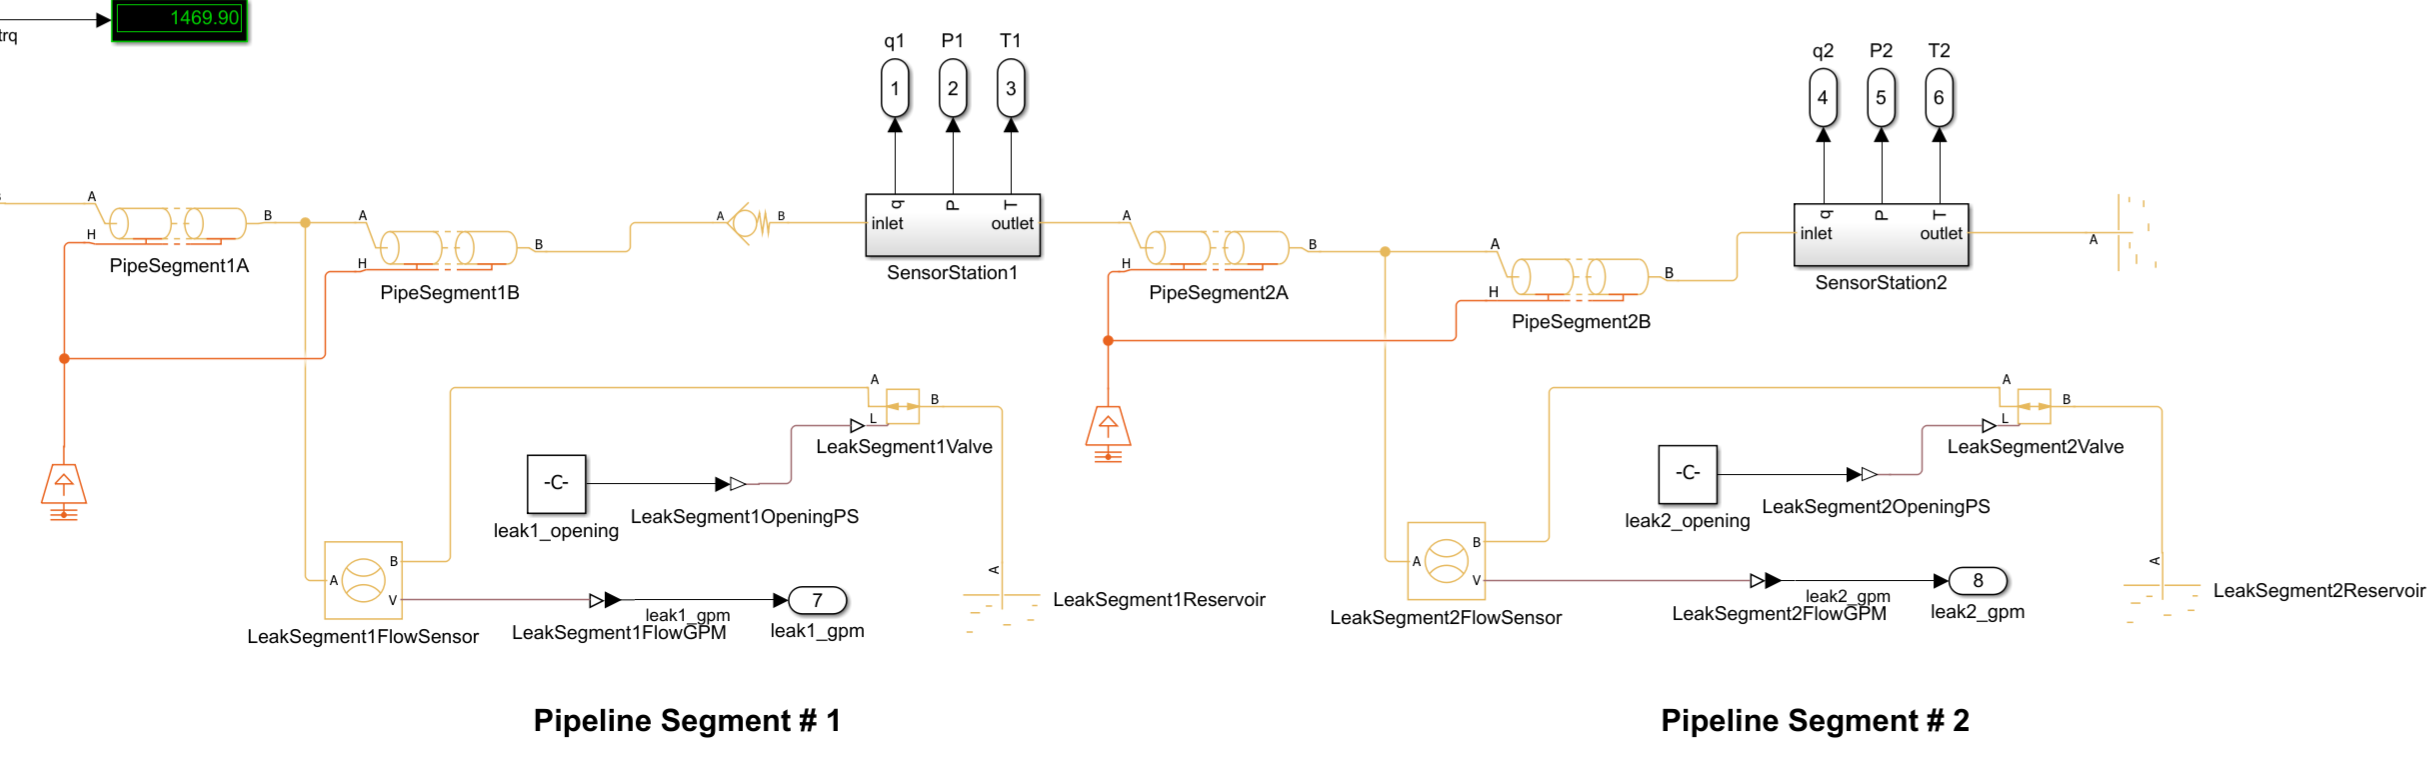

**Human Expertise matters: you, as the engineer, possess the analysis intent:** w**hat information do you need, what are the physics of the system, what modeling strategy makes sense...?**

**Pro Tip: Ask the agent to save changes to a copy instead of overriding the original files (scripts, models, etc.). In this case we saved to pipeline_with_pump_leaks.slx. These are good development practices for a human doing the work, and especially important when agents are involved.**

 
open("pipeline_with_pump_leaks.slx");

## 4. Access Data

For this step, we will create synthetic training data from the Simulink model. 

**Human Expertise matters:** It helps to understand how a condition such as a pipe leak will manifest in the sensor data outputs. For example, it would be trivial to diagnose leaks with peak pressure information at each pipe segment. However, if we only have access to flow and pressure data at the pump outlet, we need a machine learning model to decouple the effect of a leak in segment 1 vs. segment 2. Imagine how helpful this would be for a field technician that is tasked with finding and fixing the leak! 

Also, the agent initially generated code that ran the parameter sweep in series. Knowing that simulations can run in parallel with [parsim](https://www.mathworks.com/help/simulink/slref/parsim.html) allowed us to guide the agent and save a lot of simulation time.

Prompt 6:

 
Prompt6 = "I want to train a machine learning model to identify source of a leak in the system. For that, I want to generate synthetic data from the simulink model pipeline_with_pump_leaks.slx. Given that leaks in both pipe segments can impact pressure and flow sensor readings, the synthetic data shall also include the interaction of leaks in both sections. Sensor data that will be considered for the model includes flow rate sensor data and pressure data at the main pump outlet in the PumpSystem subsystem. Capture raw time series data for each run. Values of leaks in each section shall vary between 0 and 100 GPM. Create a script to run that parameter sweep and save it to the Scripts folder. Parallelize the code so that I can use multiple cores in my PC to speed up the sweep.";
clipboard("copy",Prompt6)

My results:

This step took quite a few iterations due to convergence issues in one of the simulations. In the end, the agent was able to fix the code to bypass problematic runs.

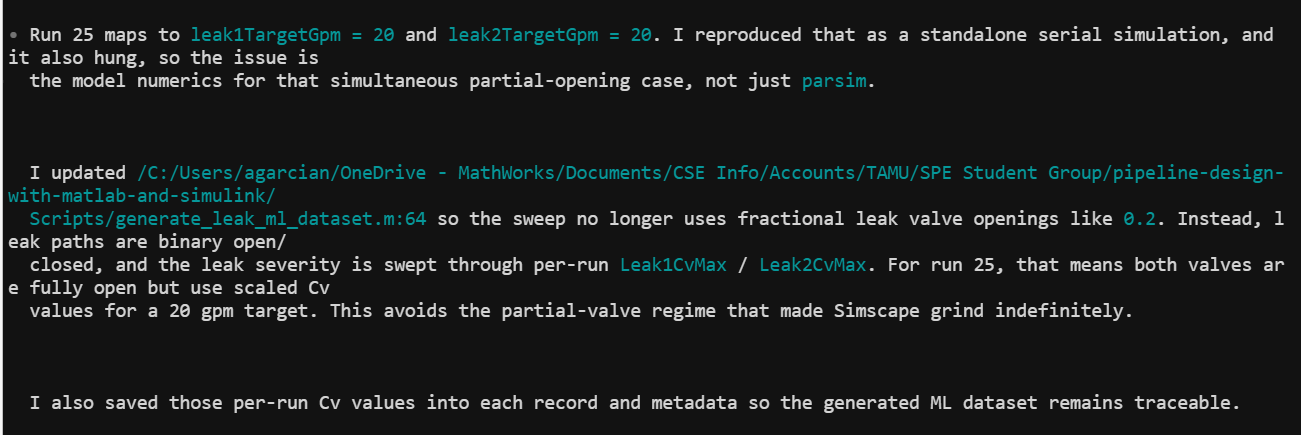

## 5. Preprocess Data

Raw time series data may not give us the information our machine learning model needs. We let the agent handle general feature extraction. We will later select the features that provide acceptable predictive power.

**Human Expertise matters: **It helps to understand proper data engineering.   

Prompt 7:

 
Prompt7 = "Create code that prepares the sweep data in the 20260915_123012 folder for training of a classification model. Extract common statistical features from pump_outlet_flow_gpm and pump_outlet_pressure_psi only. Create a summary table with nominal_leak1_gpm, nominal_leak2_gpm and extracted features. Save the script to the Scripts folder.";
clipboard("copy",Prompt7)

My results:

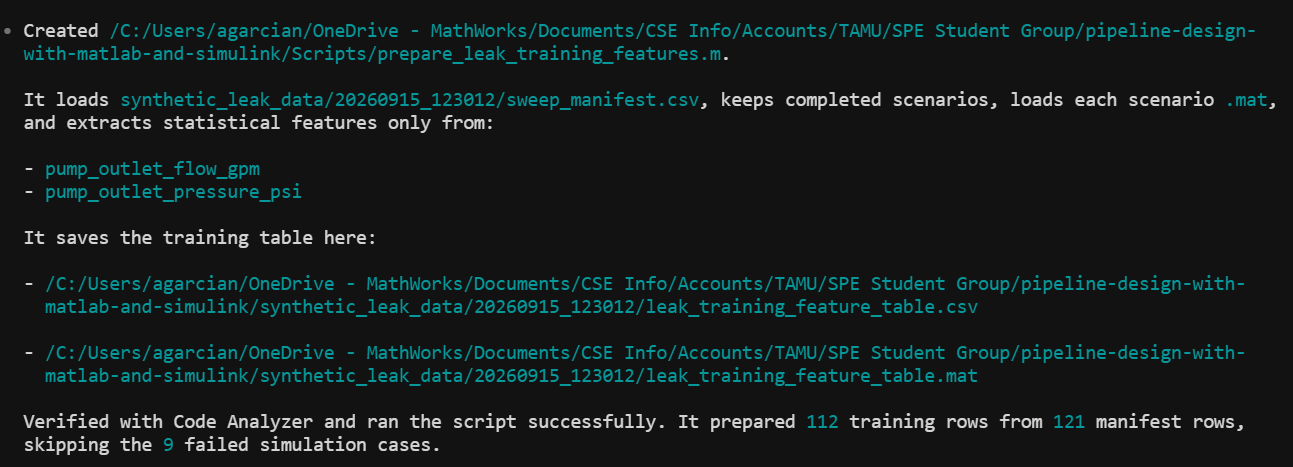

 
load("trainingFeatures.mat")
trainingFeatureTable

## 6. Develop Predictive Model

### 6.1 Train model using the Classification Learner App

[The Classification Learner app](https://www.mathworks.com/help/stats/classificationlearner-app.html) is probably a faster and more reliable way to build classification models. It provides a guided workflow for data exploration, feature selection, validation, hyperparameter optimization, model comparison, interpretability, all without requiring extensive machine learning expertise. **What's better, you can generate code from it. This code is generated deterministically to reproduce your interactive workflow!**

**Human Expertise Matters: **Knowing when agentic AI will help you move faster and when it will create more work will set you apart.

 
classificationLearner

First, we launch a new session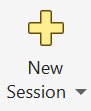

We then select the response and predictors from the dataset we prepared.

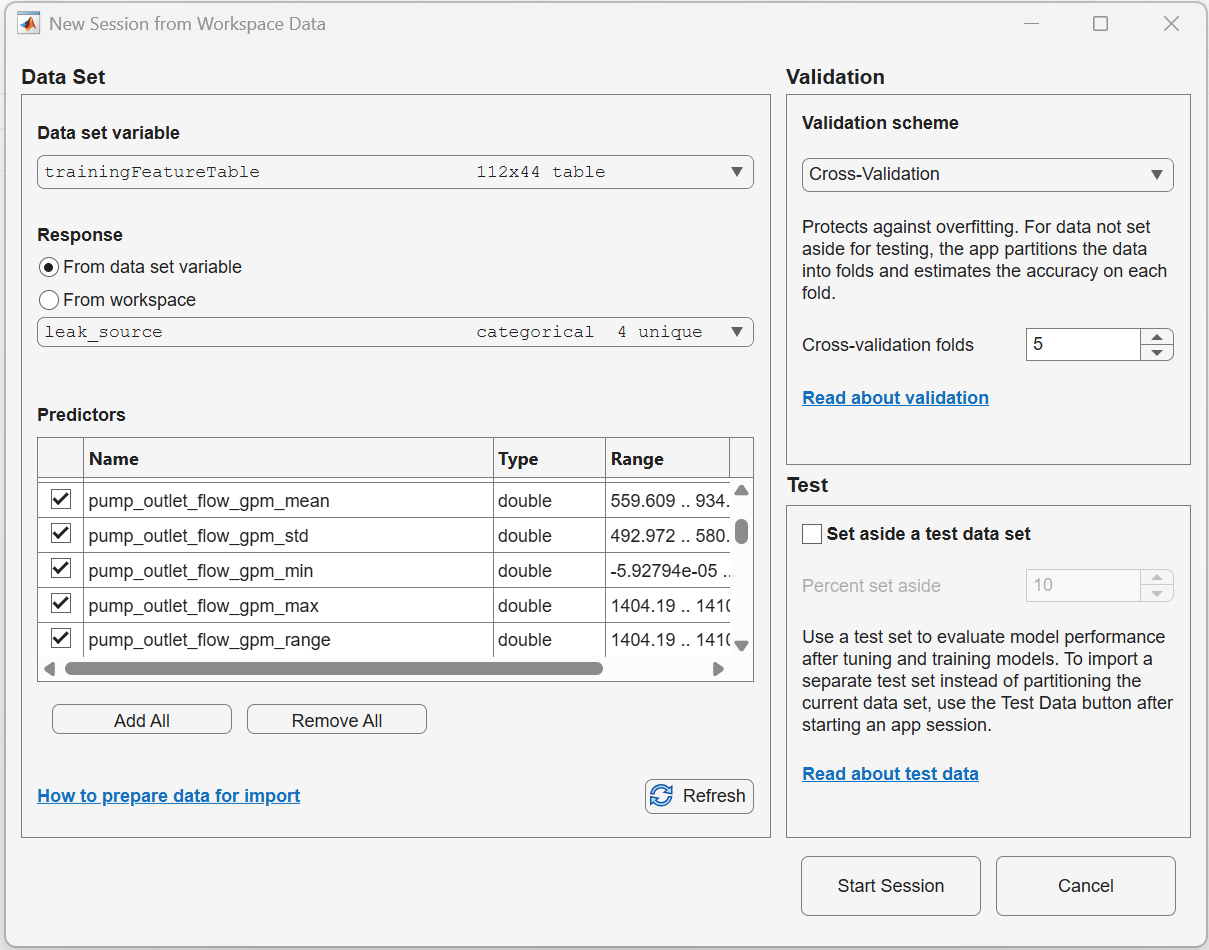

The next step involves training models and choosing one that performs well. Note that finding a model with good performance is not a guarantee - e.g. you may need more data, better data... you know, **Human Expertise Matters**

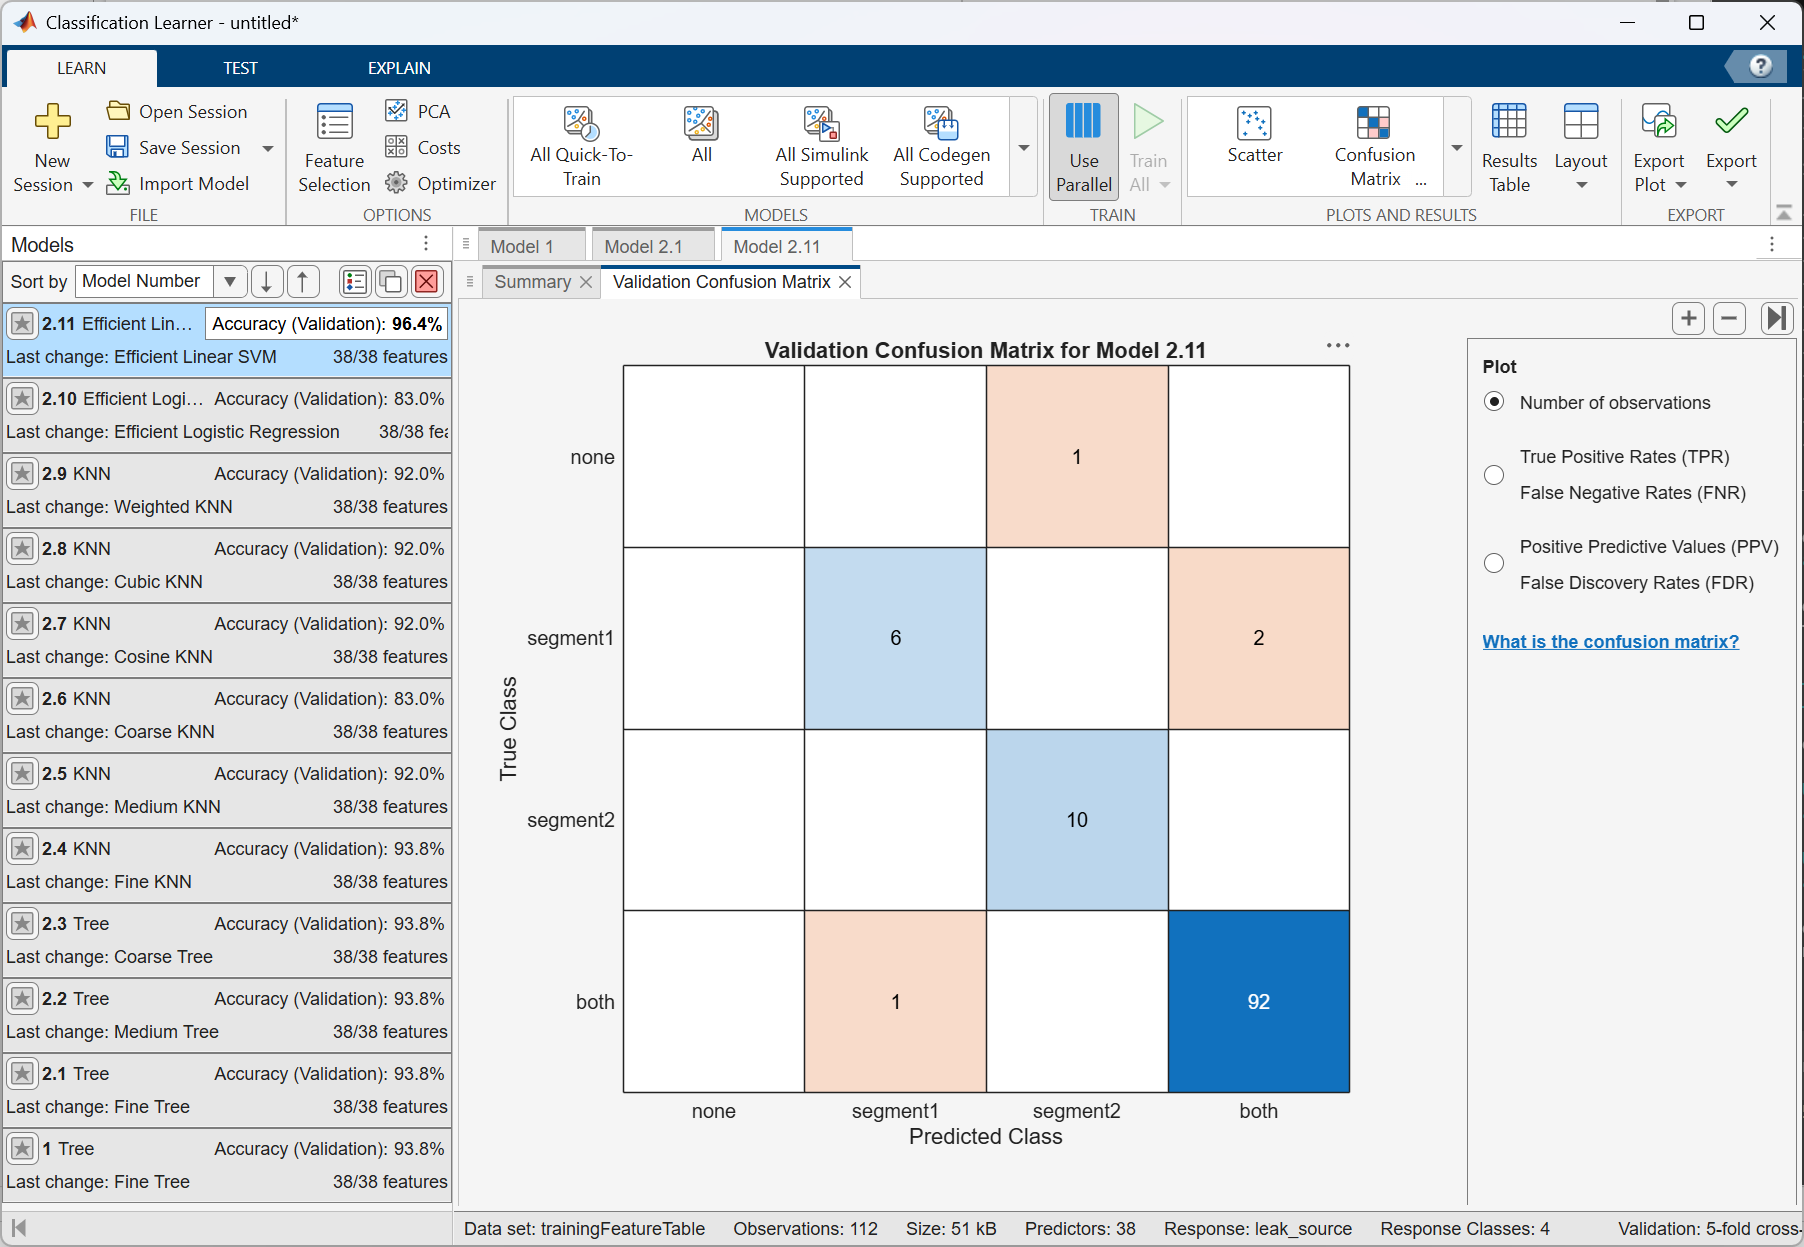

The app also let's us rank features and select the ones with the most predictive power.

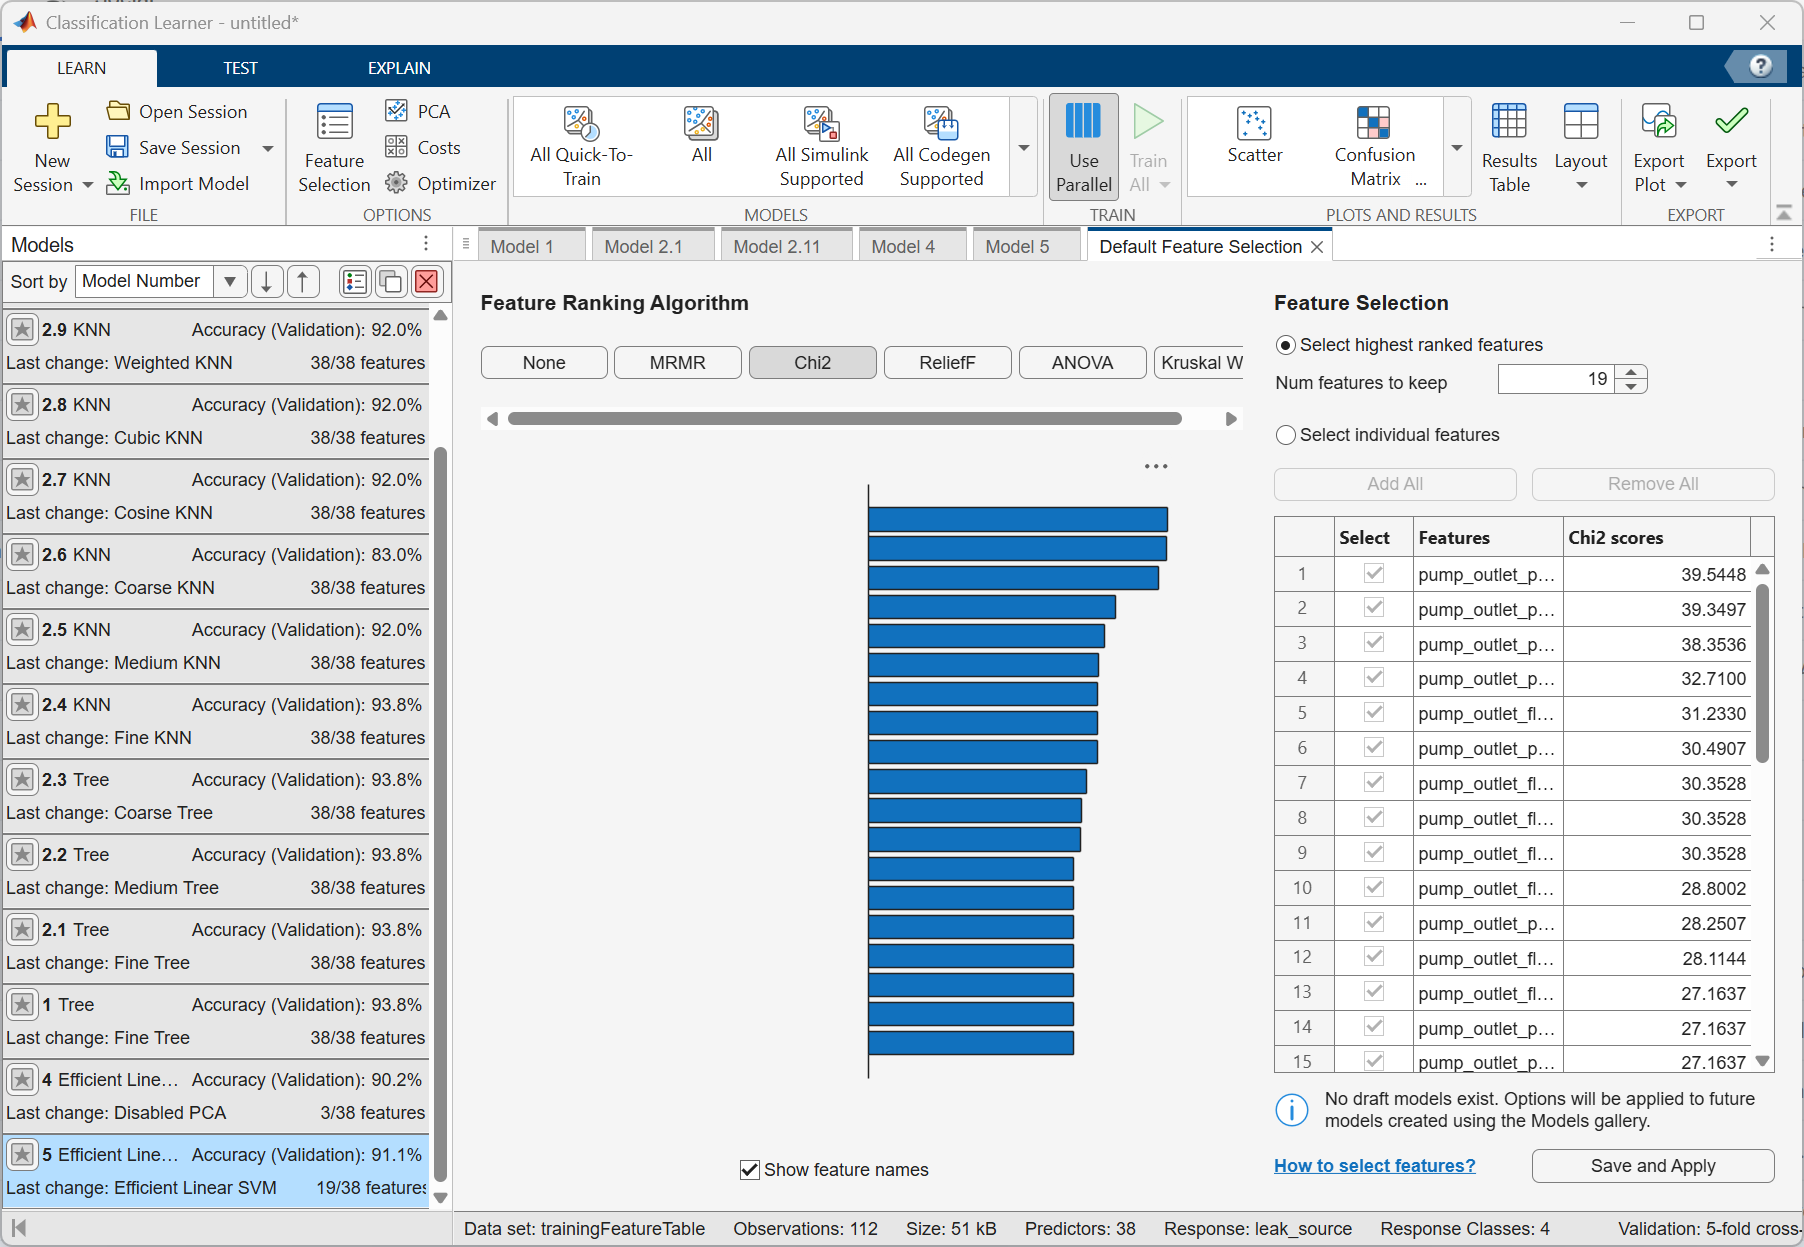

Finally, we can export the model or generate code **deterministically **to automate this step in the future.

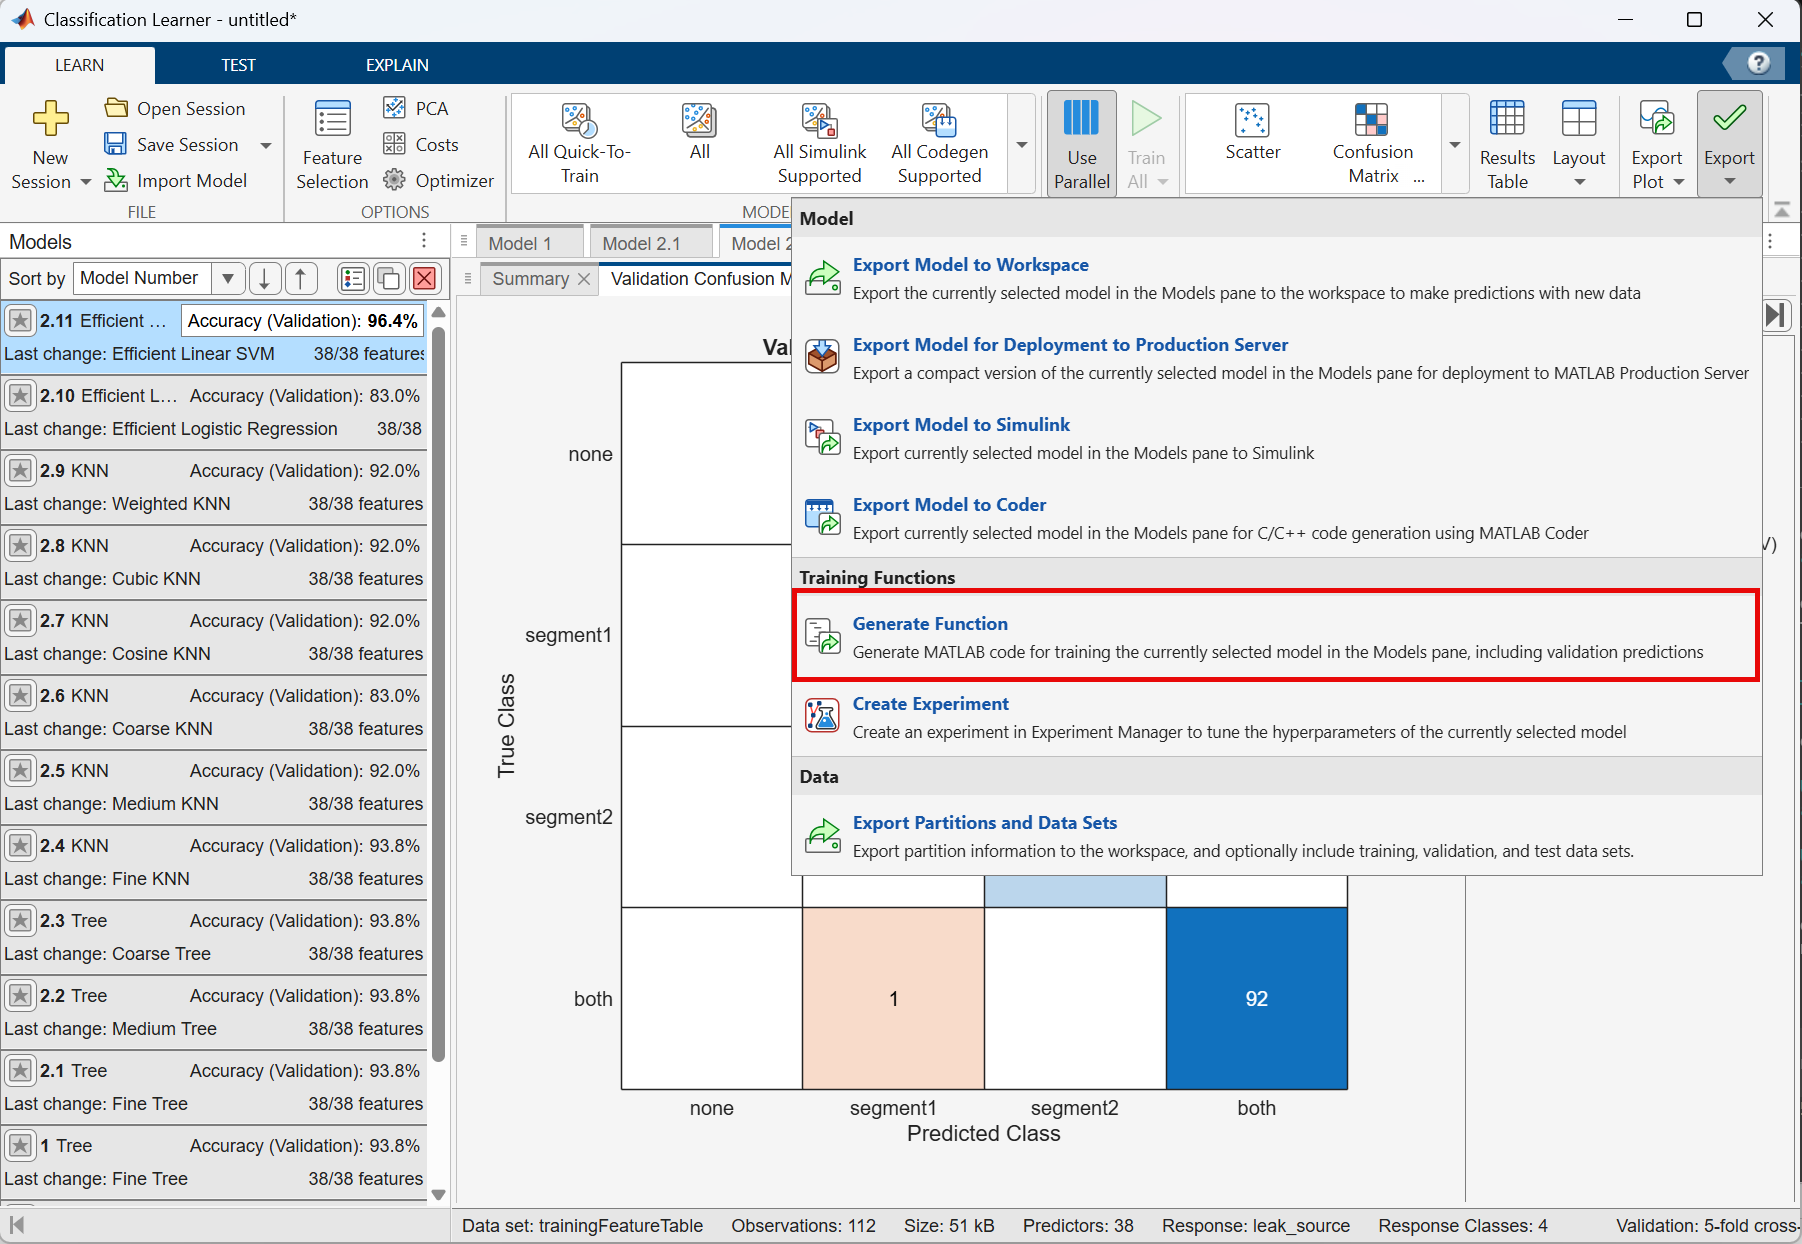

### 6.2 Test Model

Now we can use the test data we set aside to see how well our model performs with data it didn't see during training.

warning off
if ~exist('myVar','var')
    load("trainingFeatures.mat")
    [trainedClassifier, ~] = trainClassifier(trainingFeatureTable);
end
[yfit,~] = trainedClassifier.predictFcn(trainingFeatureTable); 
confusionchart(trainingFeatureTable.leak_source,yfit)

**Pro Tip: Record useful information (modifications, major milestones, edits to the initial plan, mistakes to avoid, etc.). This will help you move more efficiently and resume the work in a new session.**

Prompt 8:

 
Prompt8 = "Using the classification learner app, I created the classification model trainedModel. Familiarize yourself with this new addition to the project and log it to the example_context.md for future reference";
clipboard("copy",Prompt8)

My results:

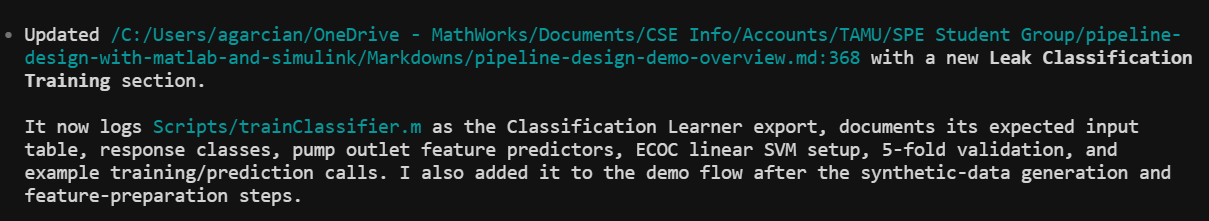

## **7. Integrate Analytics and Deploy**

Insights from your data analysis and modeling workflow need to be put to good use. For example, we may want to help a field technician assess leak condition and source with data collected from the pump. Here we create a monitoring app that leverages our predictive model. We can test it by varying model parameters and running simulations. This type of validation is known as Software-in-the-Loop (SIL) and it's a typical verification steps for software that will be deployed in the real world.

**Expertise matters: **deployment can take many forms - from an interactive app to embedded code that'll run on a micro-controller. Likewise, there are many considerations to take into account - from UI/UX best practices to hardware constraints. It helps to understand the requirements and limitations.

**Build monitoring dashboard app**

Prompt 9:

 
Prompt9 = "Create an app that: 1. Allows the user to vary elastance and resistance values in the Simulink model. The value ranges should align with those used in the synthetic data generation; 2. Allows users to simulate the Simulink model with the selected elastance and resistance values; 3. Classifies the lung condition with simulated data using the model trainedModel; 4. Displays the predicted condition with a lamp component: green for normal and red for all other classified conditions ";
clipboard("copy",Prompt9)

My results:

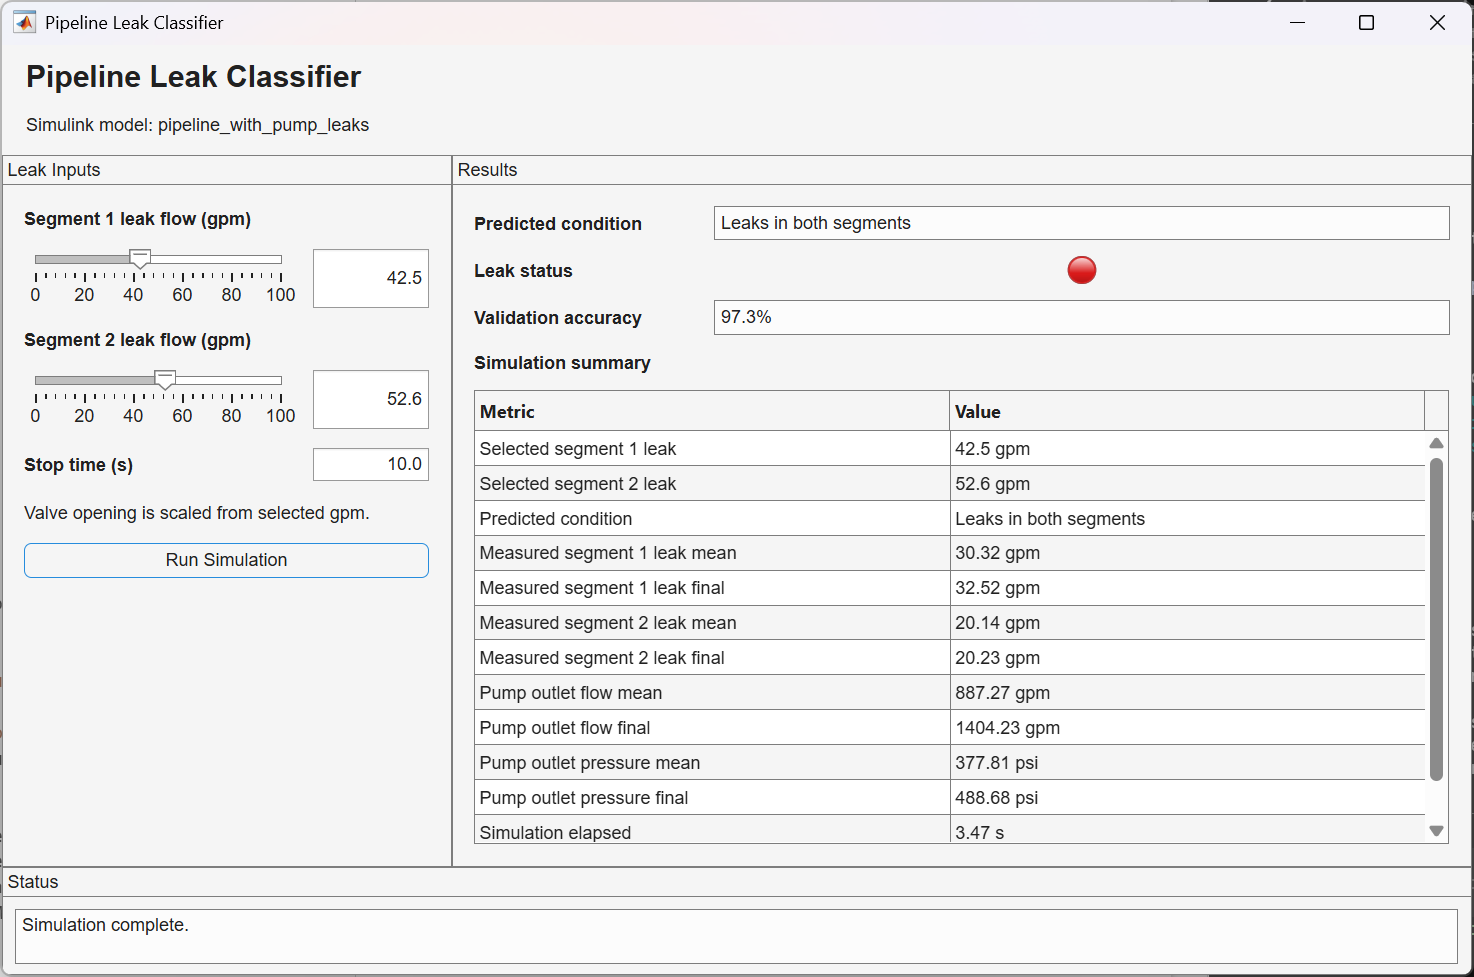

 
warning off
run('LeakClassifierApp');